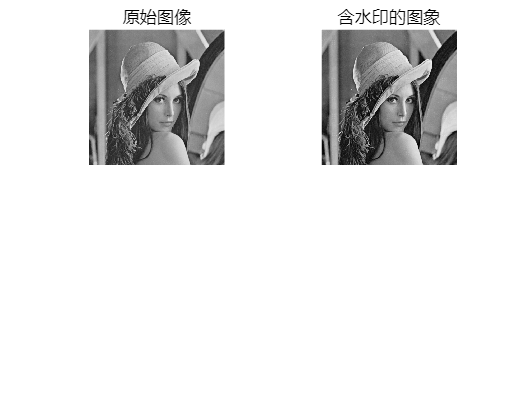

close all 
clear

siz=512; N=32;K=8; D=zeros(siz);E=15;

I=imread('lena.jpg');
O=I;
%I=rgb2gray(Y1);

subplot(2,2,1);%将彩色图像变成灰度图像

imshow(I);

title('原始图像');

I=double(I);

%读入水印

J=imread('水印(二值).bmp');

% subplot(2,2,2);
% 
% imshow(J);
% 
% title('水印图像');

%对水印缩放

% J=imresize(J,[64,64]);
% J=double(J);
% subplot(2,3,3);
% 
% imshow(J);
% 
% title('缩放水印图像');

%嵌入水印

for p=1:siz/K %为待嵌入水印的变换域的行坐标

for q=1:siz/K

x=(p-1)*K+1; y=(q-1)*K+1;

I_dct=I(x:x+K-1,y:y+K-1);%将原图分成8*8的子块

I_dct1=dct2(I_dct);%对子块进行DCT变换

if J(p,q)==0

alfa=0;

else

alfa=0.1;

end

I_dct2=I_dct1+alfa*E;

I_dct=idct2(I_dct2);

D(x:x+K-1,y:y+K-1)=I_dct;

end

end

% % 假设 K 是子块的大小，例如 K=8
% 
% DC = zeros(size/K); % 初始化 DC 系数矩阵，大小为 (size/K)×(size/K)
% 
% for p = 1:size/K % 为待嵌入水印的变换域的行坐标
%     for q = 1:size/K % 为待嵌入水印的变换域的列坐标
%         x = (p-1)*K + 1; % 子块的起始行索引
%         y = (q-1)*K + 1; % 子块的起始列索引
% 
%         I_dct = I(x:x+K-1, y:y+K-1); % 提取原图的子块
%         I_dct1 = dct2(I_dct); % 对子块进行 DCT 变换
% 
%         % 提取 DC 系数并存储到 DC_Matrix 中
%         DC(p, q) = I_dct1(1, 1); % DC 系数是 DCT 矩阵的第一个元素
%     end
% end
% [U_img,S_img,V_img] = svd(DC);
% [U1,S1,V1] = svd(J);
% new_S_img = S_img + E*S1;
% [U,S,V] = svd(new_S_img);
% DC1=U_img*S*V_img;
% 
% for p = 1:size/K % 为待嵌入水印的变换域的行坐标
%     for q = 1:size/K % 为待嵌入水印的变换域的列坐标
%         x = (p-1)*K + 1; % 子块的起始行索引
%         y = (q-1)*K + 1; % 子块的起始列索引
% 
%         I_dct = I(x:x+K-1, y:y+K-1); % 提取原图的子块
%         I_dct2 = dct2(I_dct); % 对子块进行 DCT 变换
%         I_dct2(1, 1) = DC1(p,q); 
%         I_dct=idct2(I_dct2);
%         D(x:x+K-1,y:y+K-1)=I_dct;
%     end
% end
% %D=D*512;
% imshow(D*512)

% 此时，DC_Matrix 是一个 64×64 的 DC 系数矩阵
%disp('DC 系数矩阵已生成，大小为 64×64');

subplot(2,2,2);


I=uint8(I);
D=uint8(D);
imshow(D,[]);
O1=D;
title('含水印的图象');

## 对加入水印的图像进行各种攻击

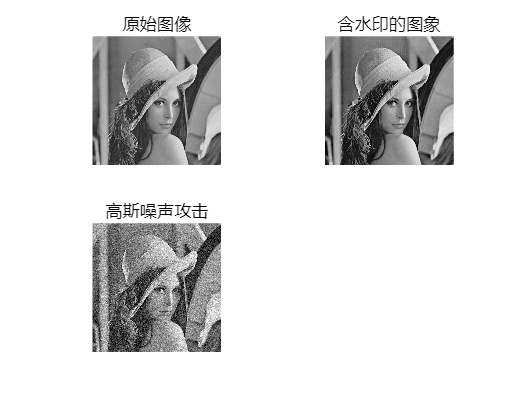

watermarked_image=D;
%攻击
%高斯滤波攻击
 % H = fspecial('gaussian',3,0.4);
 % watermarked_image = imfilter(watermarked_image,H);
 
%G 压缩攻击
%quality = 50;
%W = imresize(W, 0.5); % 缩小图像
%imwrite(W, 'temp.jpg', 'Quality', quality); % 保存为JPEG格式
%W = imread('temp.jpg'); % 重新读取JPEG图像
%W = imresize(W, 2); % 放大图像
 
% 剪切攻击
% r = 0.2; % 剪切比例为30%
% sz = size(watermarked_image);
% h1 = round(sz(1)*r); % 剪切高度
% w1 = round(sz(2)*r); % 剪切宽度
% x1 = round(rand(sz(1)-h1)); % 随机选择一行
% y1 = round(rand(sz(2)-w1)); % 随机选择一列
% watermarked_image(x1+1:x1+h1, y1+1:y1+w1) = 0; % 将指定区域置为0
 
% 旋转攻击
% angle = 10; % 旋转角度为20度
% watermarked_image = imrotate(watermarked_image, angle, 'bilinear', 'crop');

%高斯噪声
%I = im2double(I); % 将图像转换为双精度格式，范围为[0, 1]
mean = 0; % 均值为0
variance = 0.01; % 方差为0.01
watermarked_image = imnoise(watermarked_image, 'gaussian', mean, variance);

subplot(2,2,3);imshow(watermarked_image,[]);title('高斯噪声攻击');


 QQ=watermarked_image;


## 提取水印

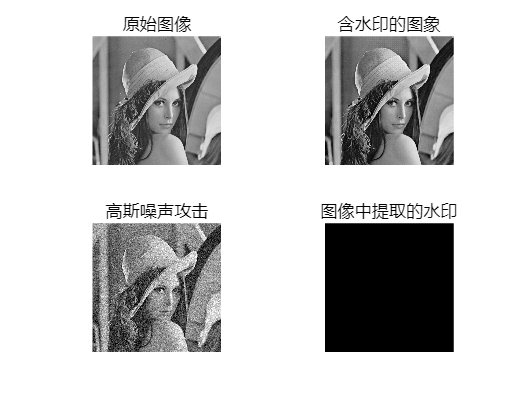

for p=1:siz/K

for q=1:siz/K

x=(p-1)*K+1;

y=(q-1)*K+1;

I1=I(x:x+K-1,y:y+K-1);

I2=QQ(x:x+K-1,y:y+K-1);

I_dct1=dct2(I1);

I_dct2=dct2(I2);

if I_dct2>I_dct1

W(p,q)=1;

else

W(p,q)=0;

end

end

end

% subplot(2,3,5);imshow(hh,[]);title('低通滤波攻击');

subplot(2,2,4);imshow(W,[]);title('图像中提取的水印');

## 评价指标

C = normxcorr2(J, W);
% 提取最大相关系数值
nc_value = max(C(:));
% 输出结果
fprintf('归一化相关性（NC）值为：%.4f\n', nc_value);

归一化相关性（NC）值为：0.0000




psnr_val = psnr(O, O1);
% 输出 PSNR 值
fprintf('PSNR 值为：%.2f dB\n', psnr_val);

PSNR 值为：46.11 dB




[ssim_value, ssim_map] = ssim(O, O1);
% 输出 SSIM 值
fprintf('SSIM 值为：%.4f\n', ssim_value);

SSIM 值为：0.9872




% 
% % 创建表格数据
% data = {
%     'NC', nc_value;
%     'PSNR', psnr_val;
%     'SSIM', ssim_value;
% };
% 
% % 创建表格
% colNames = {'Metric', 'Value'};
% 
% % 创建表格
% t = uitable('Data', data, 'ColumnName', colNames, 'Position', [20 50 200 150]);